# Slew Rate Calculations 

by Enes Ayaz 2023-09-22

You can read the articles below for more information. 

- A Review of Switching Slew Rate Control for Silicon Carbide Devices Using Active Gate Drivers.

- Analytical Loss Model for Three-Phase 1200V SiC MOSFET Inverter Drive System Utilizing Miller Capacitor-Based dv/dt-Limitation

## Background  knowledge

### High voltage and current slew rates

Wide bandgap (WBG) semiconductors like silicon carbide (SiC) devices, are approaching ideal switches due to the lower intrinsic device parasitics and reduced switching transient times; thus, the switching loss is significantly reduced compared with their silicon (Si) counterparts. Thus, in recent years,  the usage of SiC devices has increased in traction drive systems. Besides, they provide high power density through an order-of-magnitude increase in switching frequency or reduction of the DC-link capacitance.  These systems, however, must contend with the high voltage slew rate $\frac{{\textrm{dV}}_{\textrm{ds}\;} }{\textrm{dt}\;\;}$ and high current slew rate  $\frac{{\textrm{dI}}_{\textrm{ds}\;} }{\textrm{dt}\;}$.

On the one hand, a high di/dt interacts with the parasitic inductance of the power loop, which generates voltage overshoot and ringing on the gate, which might cause switches turn on and off repeatedly, namely, the self-turn-on effect. On the othe hand,  a high dv/dt slew rate may cause high-frequency noise through coupling with the heat sink or gate driver isolated power supply and finally leads to a false triggering event. Another drawback is high crosstalk noise. The fast switching transient of a device in a half-bridge configuration may interact with the Miller capacitance of the complementary side switch and results in a shoot-through event.Generally, a radical method to prevent false-triggering and shoot-through caused by high dv/dt is to minimize the parasitics of the power and gate loops. 

Furthermore,  a high dv/dt slew rate  can cause common mode voltage (CMV) issues like wearing out motor winding insulation or introducing bearing current. They can either cause failure or decrease the lifetime of the motor. Therefore, high dv/dt slew rate  should be limited considering both inverter and motor limitations. 

### Equivalent circuit and switching characteristic 

Figure below shows an equivalent circuit of a MOSFET with a  DPT setup. Its gate and source terminals are connected to a gate driver. Cgs is the gate–source capacitance. Cgd is the Miller capacitance and Cds is the drain–source capacitance. Vgs, Vds,and Vgd are the gate–source, drain–source, and gate– drain voltages, respectively. Ls , Lg,and Ld represent the parasitic inductance on the source, gate, and drain side. CL is the parasitic capacitance of the load inductor.

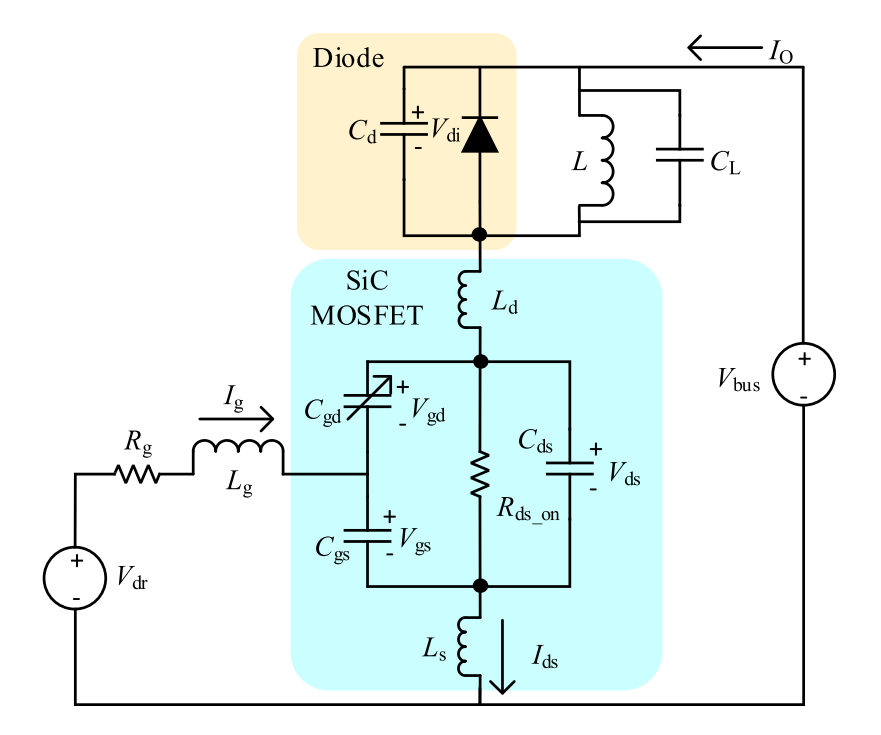

The equivalent circuit of a gate driver with a power device during the switching process can be simplified, as shown in Figure below. The intrinsic input junction capacitance of a power MOSFET, i.e., Ciss, is equal to MOSFET, the channel can be formed, and the power MOSFET Cgs + Cgd. Through charging the gate junction of the power is conducting. During the turn-off process, Ciss discharges through Rg to the power supply of the gate driver.

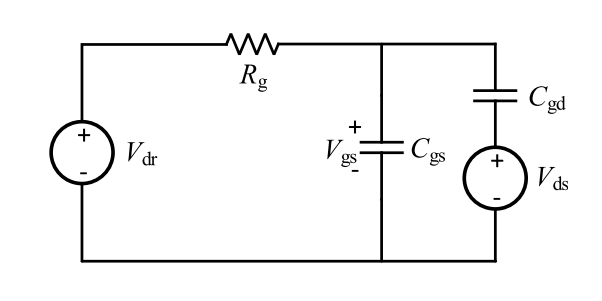

The switching transient waveforms are plotted in Figure below. High dv/dt and di/dt occur during the Miller plateau period when Cgd is charging/discharging through Rg. Correspondingly, the working principle of all slew rate control methods is to adjust the charging/discharging speed of Cgd. There are several key factors affecting the gate capacitance charging/discharging speed: gate driver voltage, gate resistance, gate current, and values of Cgs and Cgd. It should be noted that the Miller plateau of a SiC transistor is nonflat due to the low junction capacitance. The trajectory model of the SiC device is slightly different from the traditional model of silicon IGBT or MOSFET. 

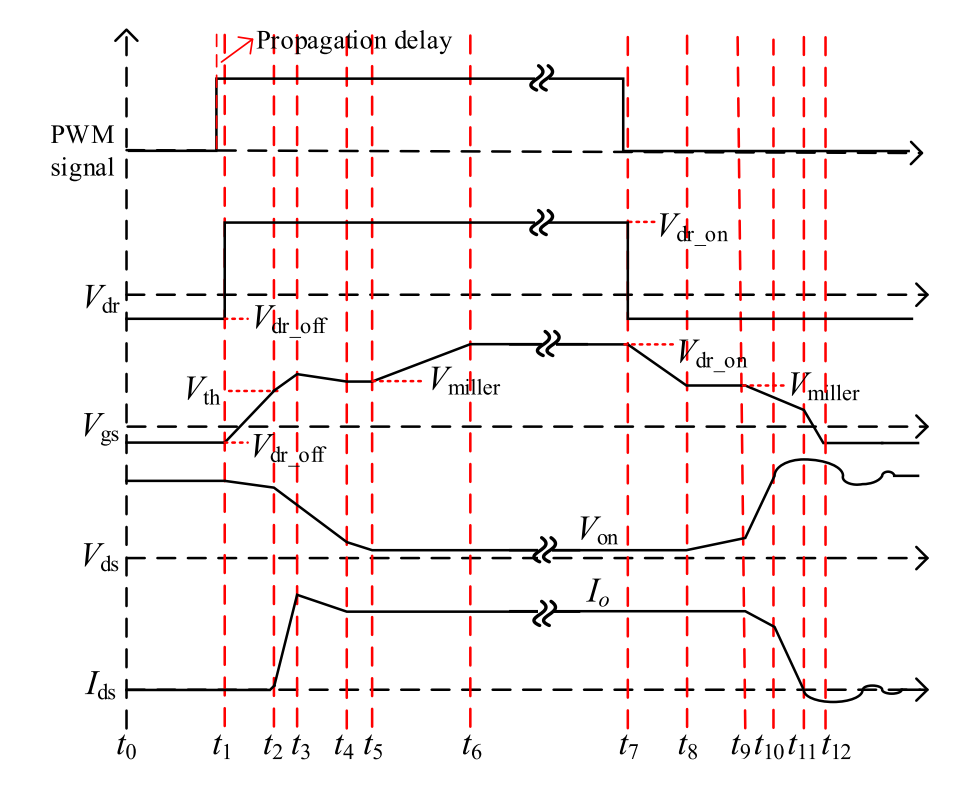

Accordingly, we can limit slew rates by various methods such as variable gate resistance method, variable input capacitance method, variable gate voltage method, and the variable gate current method.. 

### Calculation of Slew Rates 

It is necessary to study how these variables affect the switching transient and quantify their effect on the switching speed. 

#### Turn-On Process: 

t1–t2 is the turn-on delay. t2–t3 is the Ids rising time, and t3–t4 is the Vds falling time. di/dt and dv/dt can be approximately calculated by (1) and (2), respectively,

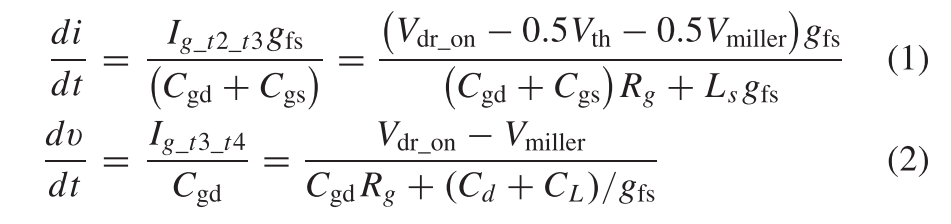

where Vmiller is the Miller plateau voltage, which is calculated is the average gate current in the period t2–t3,and Ig_t3_t4 is as Vmiller = Vth+IO/gfs and gfs is the transconductance. Ig_t2_t3 the average gate current in the period t3–t4.

#### Turn-Off Process: 

t7–t8 is the turn-off delay. t9–t10 is the Vds rising time, and t10–t11 is the Ids falling time. dv/dt and di/dt can be approximately calculated with the following equations

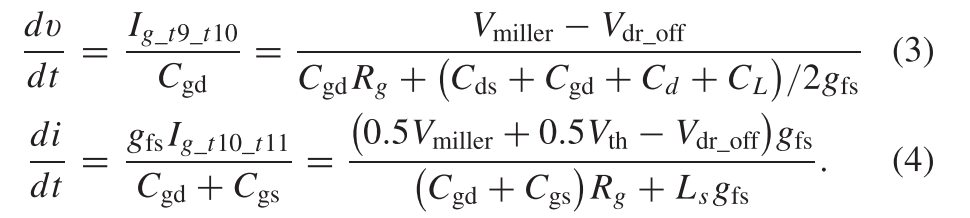

Ig_t9_t10 is the average gate current in the period t9–t10, and Ig_t10_t11 is the average gate current in the period t10– t11. The

The switching energy loss can be roughly evaluated with the following equation:

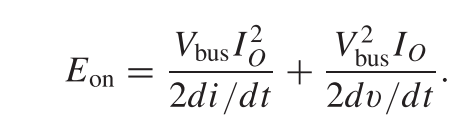

Vbus is denoted by dc bus voltage and IO is the load current. The deductions from the equations are concluded in Table below. 

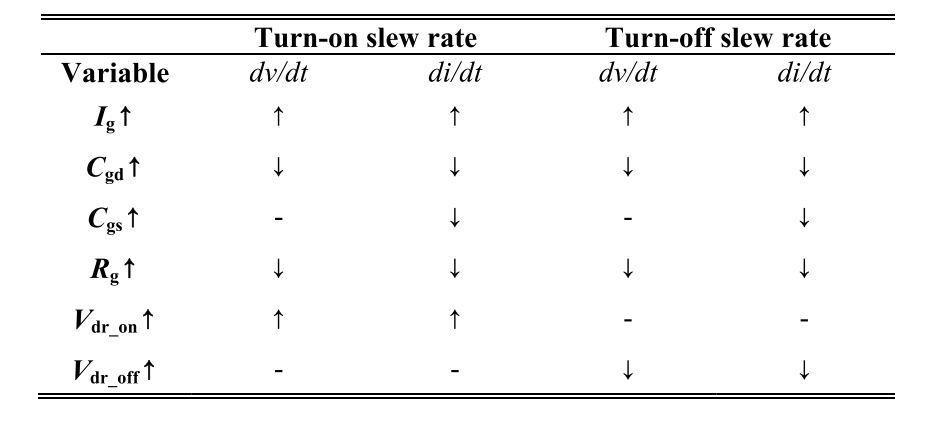

Selected Swith:  AIMBG120R080M1 CoolSiC™ 1200 V SiC Trench MOSFET

[https://www.infineon.com/dgdl/Infineon-AIMBG120R080M1-DataSheet-v01_00-EN.pdf?fileId=8ac78c8c8779172a0187c21ee84d5e7c](https://www.infineon.com/dgdl/Infineon-AIMBG120R080M1-DataSheet-v01_00-EN.pdf?fileId=8ac78c8c8779172a0187c21ee84d5e7c)

Selected Switch  :CAB006A12GM3 1200 V, 6 mΩ All-Silicon Carbide Half-Bridge Module

[https://eu.mouser.com/datasheet/2/90/CAB006A12GM3-2886938.pdf](https://eu.mouser.com/datasheet/2/90/CAB006A12GM3-2886938.pdf)

Io= 400; %A
Vbus=600; %V

di_dt_on= 18e9;  % A/sec12.5/12.5/1
dv_dt_on= 30e9; % V/sec/12


% di_dt_off= 37e9;  % A/sec
% dv_dt_off= 32e9; % V/sec

E_on=  (Vbus*Io^2)/(2*di_dt_on) + (Vbus^2*Io)/(2*dv_dt_on) ;

% E_off=  (Vbus*Io^2)/(2*di_dt_off) + (Vbus^2*Io)/(2*dv_dt_off) ;



E_on*1e3

ans = 6.0667

% E_off*1e3




## Turn-on  

Vdr_on= 15;
Vth= 2.5;
V_miller= 5.5; 
Vdr_off= -4; 


gfs=162;

Rg_int=1.12; 
Rg_ext_on=1.5;
Rg_ext_off=0;


Rg_on= Rg_int+Rg_ext_on

Rg_on = 2.6200

Rg_off= Rg_int+Rg_ext_off

Rg_off = 1.1200


Ls= 100e-9;

Ciss= 20.4e-9;
Coss= 0.79e-9;
Crss= 43e-12; 

Cgd = Crss; 
Cgs=Ciss-Crss;
Cds= Coss-Coss; 



di_dt_on= ((Vdr_on-Vth/2-V_miller/2)*gfs)/ ((Ciss*Rg_on)+(Ls*gfs))

di_dt_on = 1.0964e+08

Analytical loss model for power converters with SiC MOSFET and SiC Schottky diode pair